# MST不変量のテンソルネットワークによる計算

## 概要

Sweedler algebraをHopf algebraの具体例としてMST不変量を局所的に計算する．

テンソルネットワークの表示を持ちいて，テンソル計算を行う．

`makeTensorExpression関数を用いて，テンソルネットワークの具体的な計算を行うMATLAB式を返す関数を作成した．`

`結果として，ひものRI moveによる補空間の変化をテンソルネットワークで検出する問題への回答を与える．`

`また，fraimingの変化をキャッチする課題についても解決した．`

## `代数,定数の定義`

`SweederAlgがSweedler algebraの定義クラスである．`

`生成元を取得して，verifyHopf関数でHopf algebraの関係式をすべてチェックする．`

`エラーを出してないので，問題なく構造定数が設定されている．`

[Z,K_,E_]=SweedlerAlg.getGenerator;
Z.verifyHopf(@isequal)

Confirmed to be a Hopf algebra


構造定数をすべて取得する．ワークスペース変数を設定しておく必要がある．

Un=eye(Z.dim);
An=Z.getSC('_S');
Mu=Z.getSC('_μ');
De=Z.getSC('_Δ');
Et=Z.getSC('_η');
Ep=Z.getSC('_ε');
Ir=Z.getSC('_intr');
Il=Z.getSC('_intl');
Cr=Z.getSC('_cointr');
Cl=Z.getSC('_cointl');
Tp=TP(De,Mu,2,2);
% Tm=PE(TP(TP(De,An,2,2),De,3,2),[2 1 4 3]);
Tm=eval(makeTensorExpression('De{1,4,0}An{4,5}Mu{3,5,2}',[0 1 2 3]));


## テンソル計算

MATLABのtensorprod関数を用いたテンソルの計算を紹介する．

たとえば，o-graphのtwistingに関する補題の具体的な検証は下記のようなテンソル計算で行われる．

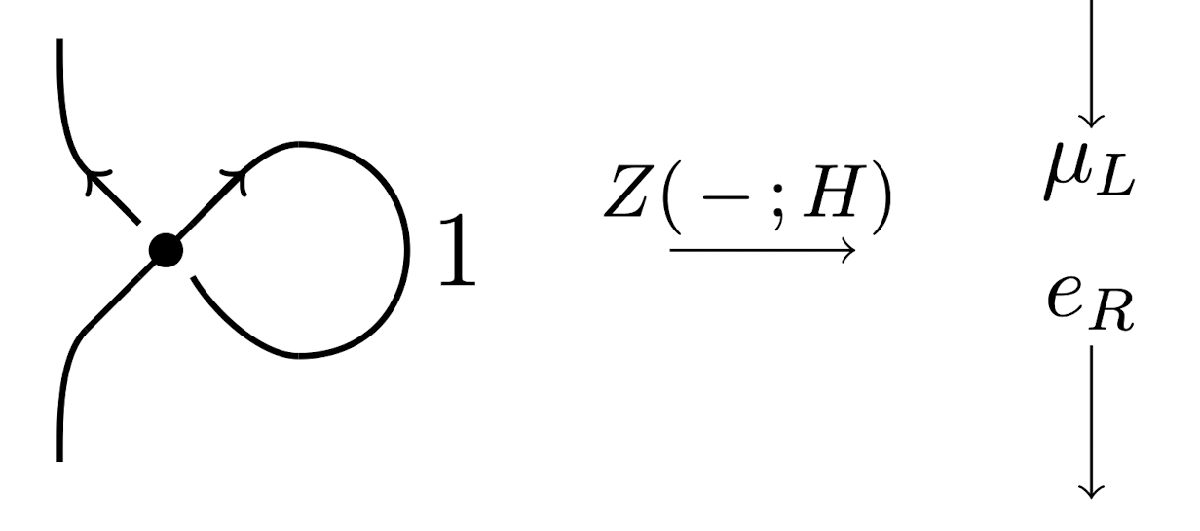

TP(TP(Mu,An^2,3,1),De,[3 2],[1 2])

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


TP(Il,Cr,N=1)

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


同じ2階テンソル(行列)が対応している．

## makeTensorExpression関数

上記の計算をより行いやすくする関数がmakeTensorExpression関数である．

上記の補題をより見やすい表記にして，図式のテンソルネットワークから，

MATLABの計算式exprを取得する事ができる．

expr=makeTensorExpression('Mu{1,2,3}Cl{3}(An^-2){1,2}',[])

expr = 'permute(tensorprod(tensorprod(1*Mu,Cl,3,1),(An^-2),[1 2],[1 2]),[1 2])'

expr=makeTensorExpression('Mu{1,2,3}(An^2){3,4}De{4,2,5}',[1 5])

expr = 'permute(tensorprod(tensorprod(1*Mu,(An^2),3,1),De,[3 2],[1 2]),[1 2])'

eval(expr)

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


expr=makeTensorExpression('Il{2}Cr{1}',[2 1])

expr = 'permute(tensorprod(1*Il,Cr,[],[],N=1),[1 2])'

eval(expr)

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


eval(makeTensorExpression('Tp{0,1,2,3}(An^2){3,0}',[2 1]))

ans =      0     0     0     0
     0     0     0     0
     0     0    -1    -1
     0     0     0     0


eval(makeTensorExpression('Tm{0,1,2,3}(An^2){0,3}',[1 2]))

ans =      1     0     0     0
     1     0     0     0
     0     0     0     0
     0     0     0     0


eval(makeTensorExpression('Ep{1}Et{2}',[1 2]))

ans =      1     0     0     0
     1     0     0     0
     0     0     0     0
     0     0     0     0


eval(makeTensorExpression('Mu{6,1,3}(An^2){3,4}De{4,5,2}An{5,6}',[1 2]))

ans =      1     1     0     0
    -1     1     0     0
     0     0    -1     1
     0     0     0     0


eval(makeTensorExpression('Ep{1}Et{2}',[1 2]))

ans =      1     0     0     0
     1     0     0     0
     0     0     0     0
     0     0     0     0


## 実例の計算

下記のテンソルネットワークの計算を行う．

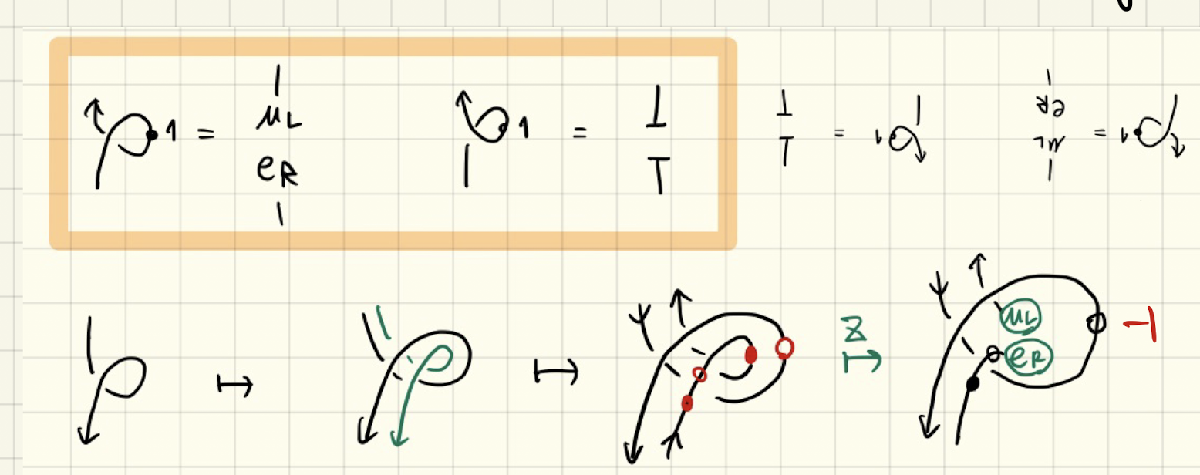

四面体の各交点に4階テンソルを対応させて，テンソルネットワークの計算を行う．

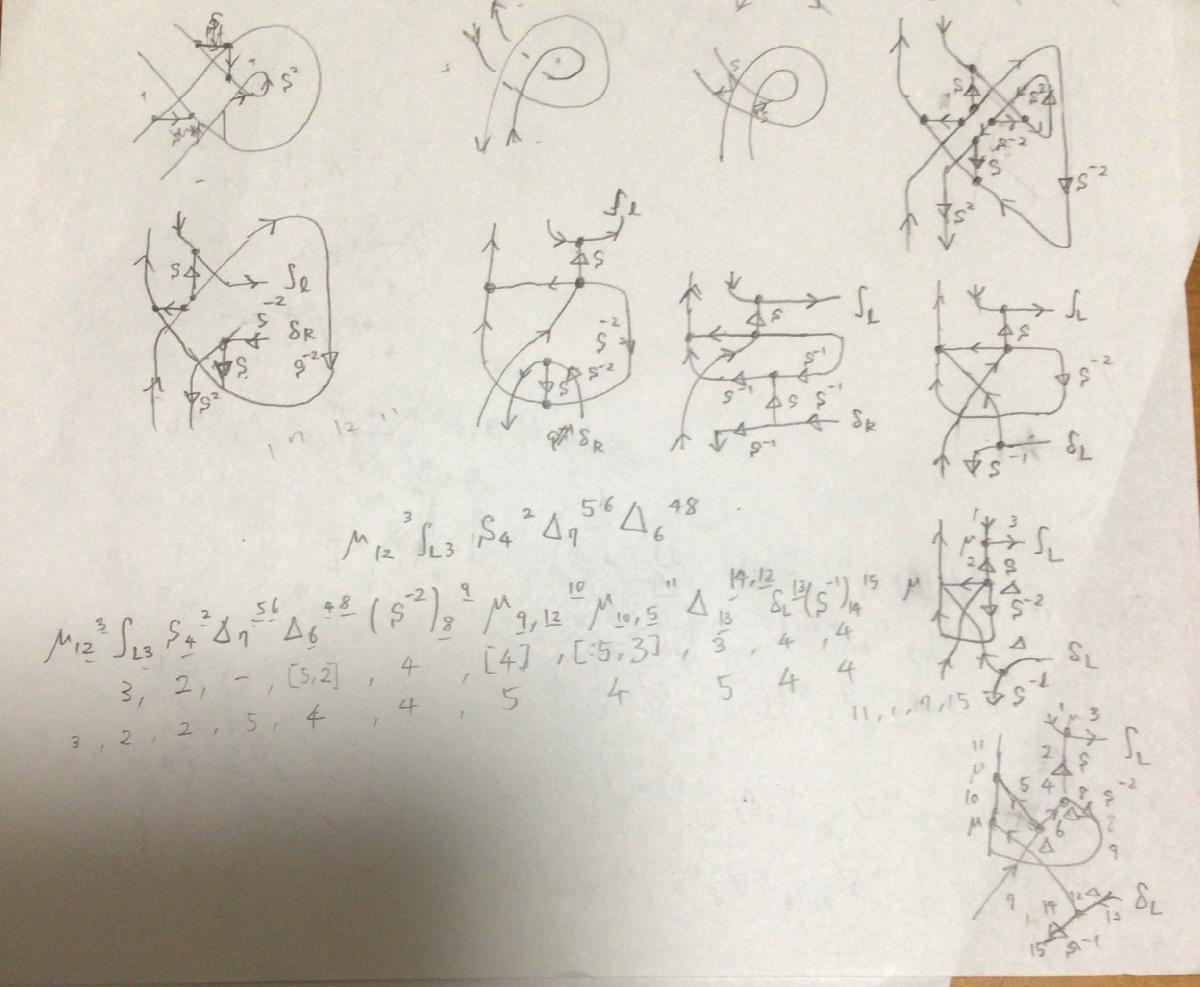

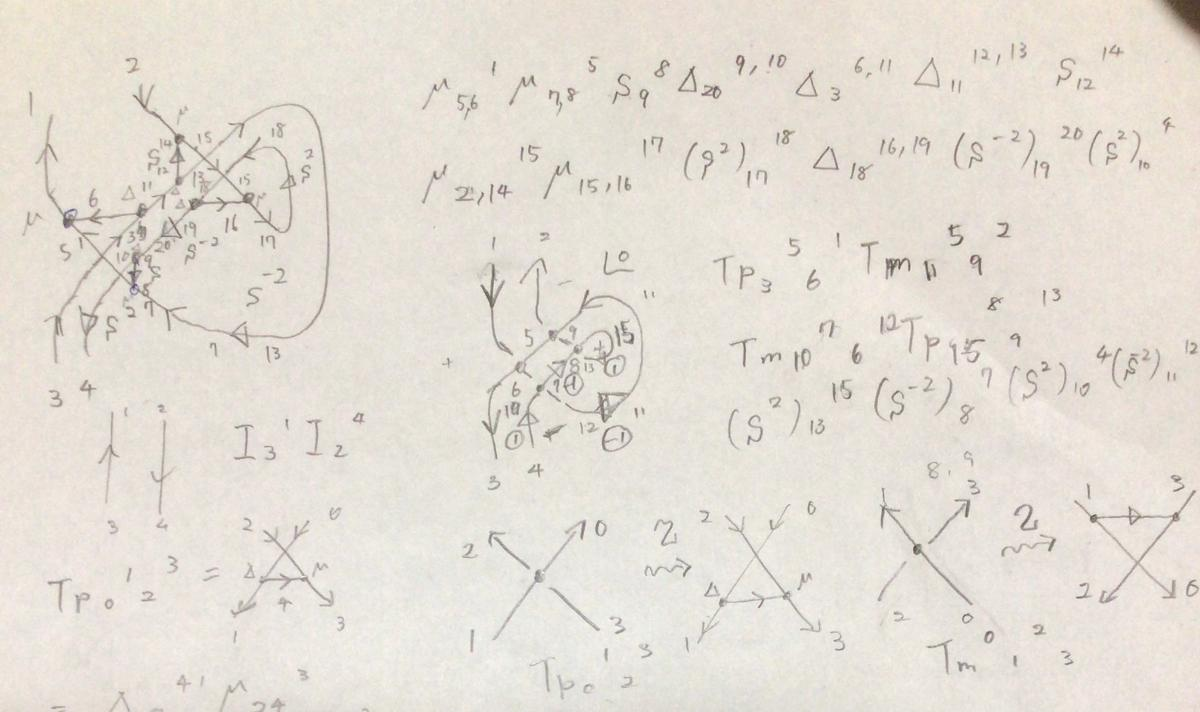

3通りの計算を行った結果，同じテンソルexpr1,expr2,expr3が得られた．

四面体を直接テンソルに書き換えるのが１番ラクな方法と思われる．

[expr,acc]=makeTensorExpression( ...
    'Mu{1,2,3}Il{3}An{4,2}De{7,5,6}De{6,4,8}(An^-2){8,9}Mu{9,12,10}Mu{10,5,11}De{13,14,12}Cl{13}(An){14,15}' ...
    ,[11 1 7 15])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Mu,Il,3,1),An,2,2),De,[],[]),De,[5 2],[1 2]),(An^-2),4,1),Mu,4,1),Mu,[5 3],[1 2]),De,3,3),Cl,4,1),(An),4,1),[3 1 2 4])'

acc =      1     7    11    15


expr1=reshape(eval(expr),16,16)

expr1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0


expr=makeTensorExpression(['Mu{5,6,1}Mu{7,8,5}An{9,8}De{20,9,10}De{3,6,11}De{11,12,13}An{12,14}' ...
    'Mu{2,14,15}Mu{15,16,17}(An^2){17,18}De{18,16,19}(An^-2){19,20}(An^2){10,4}(An^2){13,7}'],1:4)

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Mu,Mu,1,3),An,4,2),De,4,2),De,1,2),De,6,1),An,6,1),Mu,7,2),Mu,8,1),(An^2),9,1),De,[9 8],[1 2]),(An^-2),[8 3],[1 2]),(An^2),3,1),(An^2),[4 2],[1 2]),[1 3 2 4])'

expr2=reshape(eval(expr),16,16)

expr2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0


isequal(expr1,expr2)

ans = logical
   1

disp(expr1)

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0
     1     0     0     0     0

disp(sum(abs(expr1)))

     1     1     1     1     1     1     1     1     1     1     3     3     1     1     3     3


expr=makeTensorExpression(['Tp{3,5,6,1}Tm{11,5,9,2}Tm{10,7,6,12}Il{9}Cr{8}(An^-2){8,7}(An^2){10,4}(An^-2){11,12}'],1:4)

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,2,2),Tm,2,3),Il,4,1),Cr,[],[]),(An^-2),[8 6],[1 2]),(An^2),5,1),(An^-2),[3 5],[1 2]),[2 3 1 4])'

expr3=reshape(eval(expr),16,16)

expr3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0


isequal(expr1,expr3)

ans = logical
   1

## 問1に関する考察

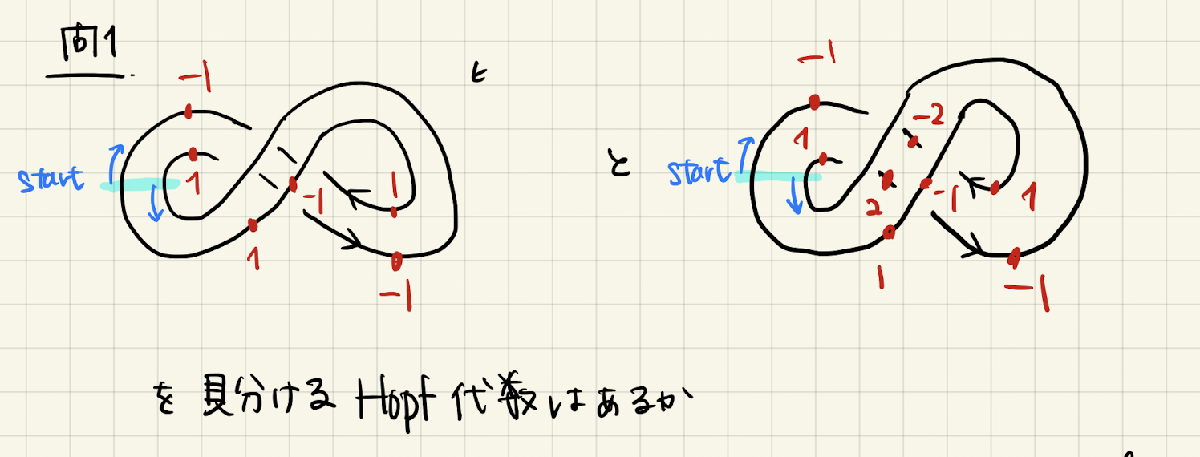

Sweedlerではframingの変化をキャッチ出来なかった．$S^4 =\textrm{id}$であることが原因と思われる．

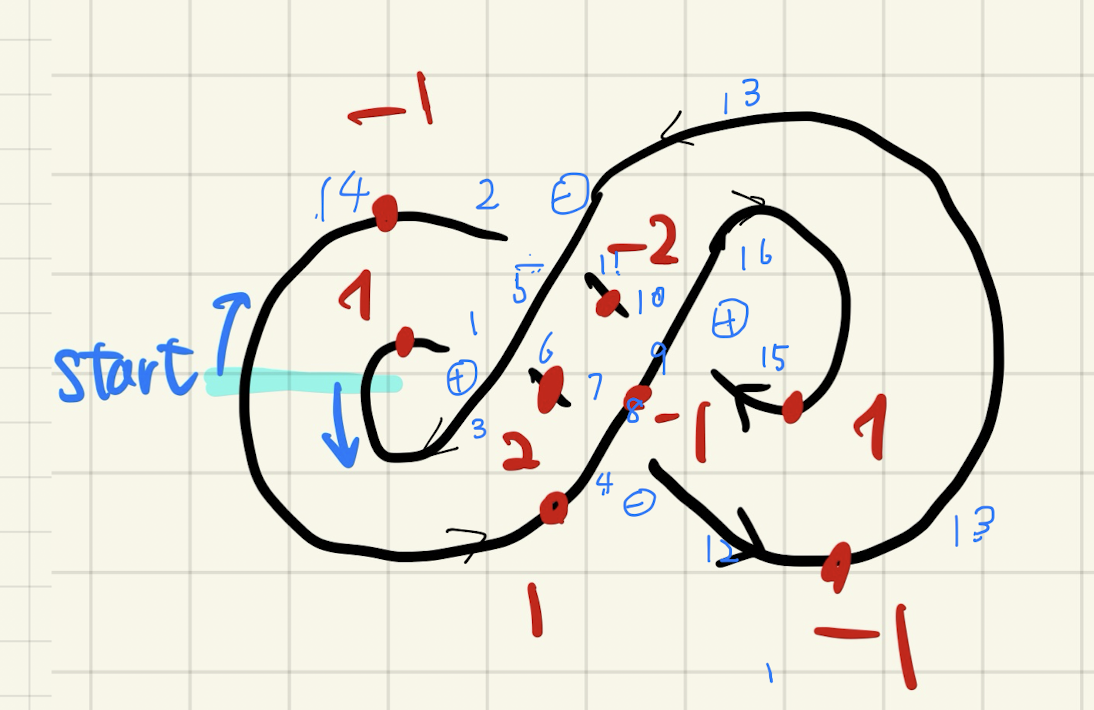

expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(An^4){7,6}(An^-2){9,8}(An^-4){11,10}(An^2){1,3}(An^-2){14,2}(An^2){15,16}(An^-2){13,12}(An^2){4,14}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),Tp,[],[]),(An^4),[10 2],[1 2]),(An^-2),[10 6],[1 2]),(An^-4),[5 9],[1 2]),(An^2),[2 1],[1 2]),(An^-2),2,2),(An^2),[5 4],[1 2]),(An^-2),[1 3],[1 2]),(An^2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 2

expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(Un){7,6}(An^-2){9,8}(Un){11,10}(An^2){1,3}(An^-2){14,2}(An^2){15,16}(An^-2){13,12}(An^2){4,14}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),Tp,[],[]),(Un),[10 2],[1 2]),(An^-2),[10 6],[1 2]),(Un),[5 9],[1 2]),(An^2),[2 1],[1 2]),(An^-2),2,2),(An^2),[5 4],[1 2]),(An^-2),[1 3],[1 2]),(An^2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 2

expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(Un){7,6}(An^-2){9,8}(Un){11,10}(An^2){1,3}(Un){4,2}(An^2){15,16}(An^-2){13,12}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),Tp,[],[]),(Un),[10 2],[1 2]),(An^-2),[10 6],[1 2]),(Un),[5 9],[1 2]),(An^2),[2 1],[1 2]),(Un),[3 2],[1 2]),(An^2),[4 3],[1 2]),(An^-2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 2

ring=TP(Tp,An^-2,[1 2],[1 2])

ring =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


TP(De,An^2,1:2,1:2)

ans =      0
     0
     0
     0


expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}Tp{16,9,10,15}' ...

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),Tp,[],[]),(An^4),[10 2],[1 2]),(An^-2),[10 6],[1 2]),(An^-4),[5 9],[1 2]),(An^2),[2 1],[1 2]),(An^-2),2,2),(An^2),[5 4],[1 2]),(An^-2),3,2),ring,[1 4],[1 2]),(An^2),[1 2],[1 2]),[1 2])'

ans = 0

    '(An^4){7,6}(An^-2){9,8}(An^-4){11,10}(An^2){1,3}(An^-2){14,2}(An^2){15,16}(An^-2){17,12}ring{13,17}(An^2){4,14}'])
eval(expr)

## 小さい量子群のBorel部分代数$u_q(\mathfrak{sl}_2^+)$の導入

$E,K
$を生成元,$q=\exp(2\pi i/N),~~E^N=0, ~~K^N=1,~~KE=qEK$を関係式とする代数を導入する．

これは$N^2$次元のホップ代数の構造が入る．N=3で計算を行う．

(N=5だとメモリを遥かに上回る2TBが計算に要求されたのでやめた．次元の問題は深刻である)

N=3;
[Z,K,E]=Uqsl2BorelSmall.getGenerator(N)

Z =     coeff    base
    _____    ____
      0       -  

K =     coeff    base
    _____    ____
      1      K^1 

E =     coeff    base
    _____    ____
      1      E^1 

Z.verifyHopf(@(x,y)all(eqD(x,y,1e-5),"all"))

Confirmed to be a Hopf algebra


関係式はこれでチェックできる．そして構造定数を取得する．

Un=eye(Z.dim);
An=Z.getSC('_S');
Mu=Z.getSC('_μ');
De=Z.getSC('_Δ');
Et=Z.getSC('_η');
Ep=Z.getSC('_ε');
Ir=Z.getSC('_intr');
Il=Z.getSC('_intl');
Cr=Z.getSC('_cointr');
Cl=Z.getSC('_cointl');
Tp=TP(De,Mu,2,2);
Tm=TP(TP(De,An,2,1),Mu,3,2);


expr=makeTensorExpression(['Tp{5,3,6,1}(An^4){7,6}(An^2){1,3}Tm{5,13,2,11}(An^-2){13,12}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(An^-2){9,8}(An^-4){11,10}(An^-2){14,2}(An^2){15,16}(An^2){4,14}']);
eval(expr)

ans = -6.0000 + 0.0000i

expr=makeTensorExpression(['Tp{5,3,6,1}(Un){7,6}(An^2){1,3}Tm{5,13,2,11}(An^-2){13,12}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(An^-2){9,8}(Un){11,10}(An^-2){14,2}(An^2){15,16}(An^2){4,14}']);
eval(expr)

ans = 7.5000 + 2.5981i

expr=makeTensorExpression(['Tp{5,3,6,1}(Un){7,6}(An^2){1,3}Tm{5,13,2,11}(An^-2){13,12}Tm{8,4,12,7}Tp{16,9,10,15}' ...
    '(An^-2){9,8}(Un){11,10}(Un){4,2}(An^2){15,16}']);
eval(expr)

ans = 7.5000 + 2.5981i

#### 値が異なるので，$N=3,\;q=\exp \left(2\pi i/3\right)$としたときのホップ代数はframingの変化をキャッチしているといえる．

わっかを付け加える操作はUq(sl2+)の場合は0にすることと対応する？

abs(TP(De,An^2,1:2,[2 1]).')

ans = 1.0e-14 *

    0.0598    0.1724    0.1897    0.1419    0.0558         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


## 群環の導入

巡回群で計算してみる．

[Zc,One]=CyclicGroupAlg.getGenerator(5)

Zc =     coeff    base
    _____    ____
      0       -  

One =     coeff    base
    _____    ____
      1       e1 

Zc.verifyHopf(@isequal)

Confirmed to be a Hopf algebra


(1+One)*(1+One^2)*(1+One^4)

ans =     coeff    base
    _____    ____
      2       e0 
      2       e1 
      2       e2 
      1       e3 
      1       e4 

Delta(One)

ans =     coeff     base  
    _____    _______
      1      e1 ⊗ e1

Zc.dispInt

                   coordinates     
              _____________________
    intr      1    0    0    0    0
    cointr    1    1    1    1    1
    intl      1    0    0    0    0
    cointl    1    1    1    1    1


Group algebraはunimodular & counimodularである．

## 問2の考察(続き)

Sweedlerの場合で引き続き計算を実行した．

#### **結果として，twist1~4でそれぞれ違うテンソル(16×16行列)が得られた．**

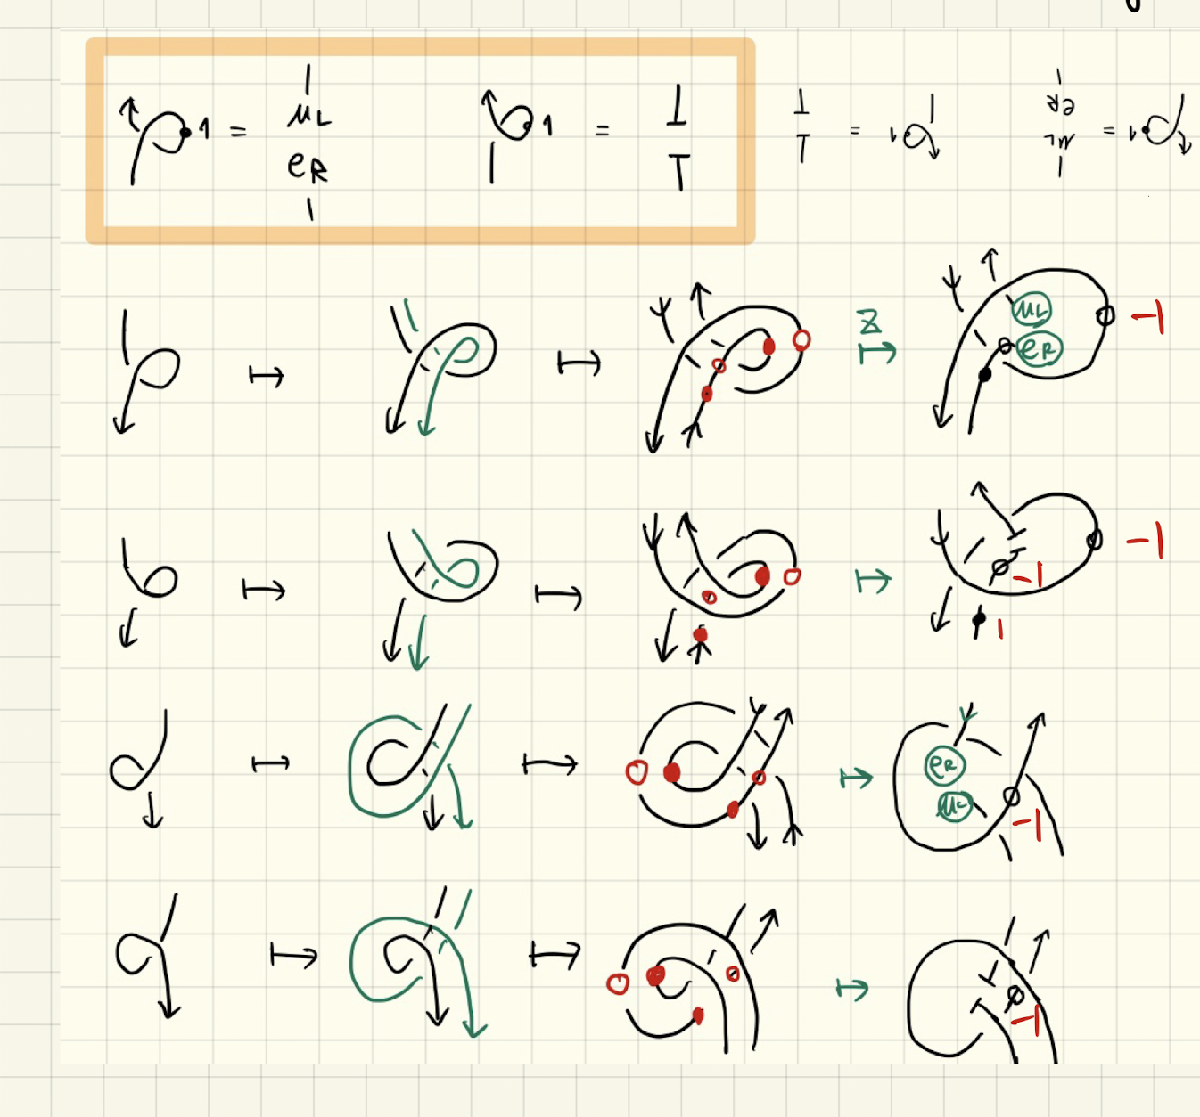

twist=cell(1,4);
twist{1}=reshape(eval(makeTensorExpression( ...
    'Tp{3,5,6,1}Tm{11,5,9,2}Tm{10,7,6,12}Tp{15,8,9,13}(An^2){13,15}(An^-2){8,7}(An^2){10,4}(An^-2){11,12}' ...
    ,1:4)),numel(Un)*[1 1]);
twist{2}=reshape(eval(makeTensorExpression( ...
    'Tm{1,6,5,3}Tp{2,9,5,11}Tp{12,6,7,10}Tm{13,9,8,15}(An^2){13,15}(An^-2){8,7}(An^2){10,4}(An^-2){11,12}' ...
    ,1:4)),numel(Un)*[1 1]);
twist{3}=reshape(eval(makeTensorExpression( ...
    'Tp{3,5,1,6}Tm{5,11,2,9}Tm{7,10,12,6}Tp{8,15,13,9}(An^2){15,13}(An^-2){7,8}(An^2){4,10}(An^-2){12,11}' ...
    ,1:4)),numel(Un)*[1 1]);
twist{4}=reshape(eval(makeTensorExpression( ...
    'Tm{3,5,1,6}Tp{9,2,11,5}Tp{6,12,10,7}Tm{9,13,15,8}(An^2){15,13}(An^-2){7,8}(An^2){4,10}(An^-2){12,11}' ...
    ,1:4)),numel(Un)*[1 1]);
expr=false(4,4);
for ii=1:4
    for jj=1:4
        expr(ii,jj)=isequal(twist{[ii,jj]});
    end
    disp("twist["+ii+"]")
    disp(twist{ii})
end

twist[1]


     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0
     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0
     1     0     0     0     0

twist[2]


     1     0     0     0     0     1     0     0     0     0     0     0     0     0     0     1
     0    -1     0     0     1     0     0     0     0     0     0     1     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0
     0     1     0     0    -1     0     0     0     0     0     0     0     0     0     1     0
     1     0     0     0     0     1     0     0     0     0     1     0     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0
    -1     0     0     0     0

twist[3]


     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     0     0     0     1     0     0     0     0     0     1     0     0     0     0     0
     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0    -1
     0     0     0     0     0     1     0     0     0     0     0    -1     0     0     0     0
     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     0     0    -2    -1     0     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0    -2     1     0     0
     0     0     0     0    -1

twist[4]


     1     1     0     0     1     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     1     0
     0     0    -2    -1     0     0    -1    -2    -1     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     1
    -1     1     0     0     1    -1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     0     0    -2     1     0     1     0     0    -1     0     0     0
     0     0     0     0     0     0     0     0    -1     0     0     0     0    -1     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0

disp(expr) %twist1,2,3,4が互いに等しいかどうか　

   1   0   0   0
   0   1   0   0
   0   0   1   0
   0   0   0   1


## リングを付け足す操作について

二重化されたavalonに下記のリングを付け足す操作での変化を見る．

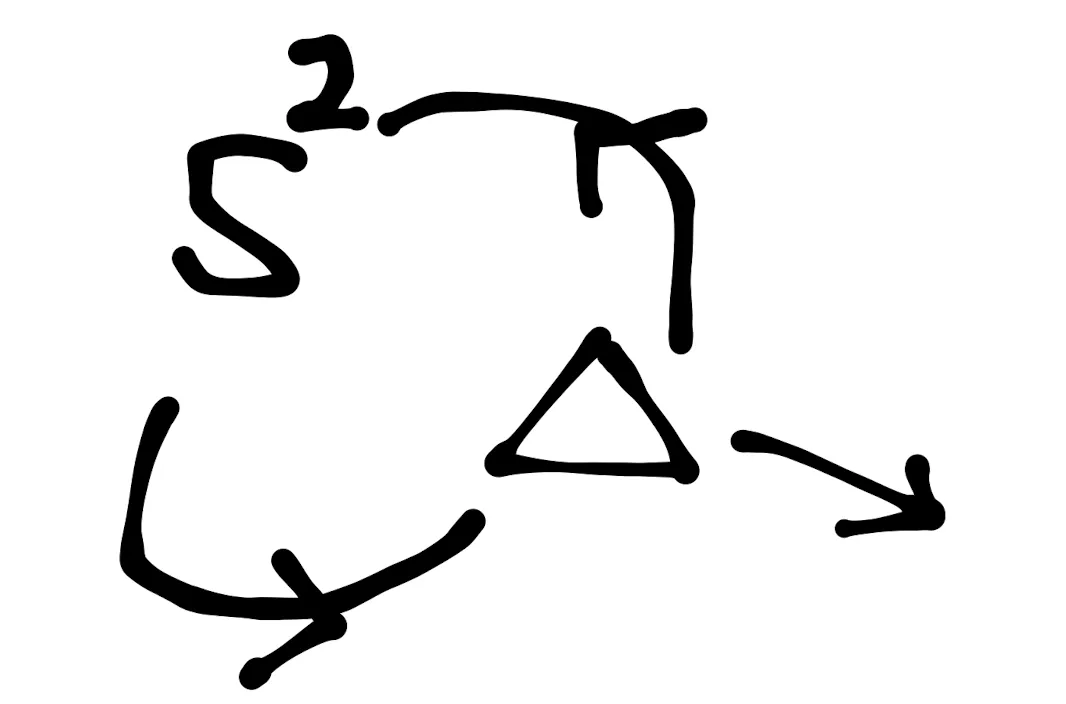

のテンソルは$u_q \left({\mathrm{sl}}_2^+ \right)$だと0になるようである(数値的に)

N=5での計算例)

ring=TP(Tp,An^-2,[1 2],[1 2])

ring = 1.0e-14 *

  -0.1055 - 0.1221i  -0.1055 - 0.0999i  -0.2220 - 0.1221i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.2220 - 0.1221i  -0.1055 - 0.1221i  -0.1055 - 0.0999i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.1055 - 0.0999i  -0.2220 - 0.1221i  -0.1055 - 0.1221i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1055 - 0.1221i  -0.0333 + 0.1332i   0.2314 - 0.1279i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.2314 - 0.1279i  -0.1055 - 0.1221i  -0.0333 + 0.1332i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0333 + 0.1332i   0.2314 - 0.1279i  -0.1055 - 0.1221i   0.000

なので，ringをつなげると，不変量の値は0になる．

cyclic group algebraの場合はringのテンソルは下記のような行列となる．

group algebraの場合は変化は無かった

ring=TP(Tp,An^-2,[1 2],[1 2])

ring =      1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1
     1     1     1     1     1


expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}(An^-2){9,8}Tp{16,9,10,15}' ...
    '(An^4){7,6}(An^-4){11,10}(An^2){1,3}(An^-2){14,2}(An^2){15,16}ring{13,17}(An^-2){17,12}(An^2){4,14}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),(An^-2),7,2),Tp,10,2),(An^4),[9 2],[1 2]),(An^-4),[5 9],[1 2]),(An^2),[2 1],[1 2]),(An^-2),2,2),(An^2),[5 4],[1 2]),ring,1,1),(An^-2),[4 2],[1 2]),(An^2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 5

expr=makeTensorExpression(['Tp{5,3,6,1}Tm{5,13,2,11}Tm{8,4,12,7}(An^-2){9,8}Tp{16,9,10,15}' ...
    '(An^4){7,6}(An^-4){11,10}(An^2){1,3}(An^-2){14,2}(An^2){15,16}Un{13,17}(An^-2){17,12}(An^2){4,14}'])

expr = 'permute(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(tensorprod(1*Tp,Tm,1,1),Tm,[],[]),(An^-2),7,2),Tp,10,2),(An^4),[9 2],[1 2]),(An^-4),[5 9],[1 2]),(An^2),[2 1],[1 2]),(An^-2),2,2),(An^2),[5 4],[1 2]),Un,1,1),(An^-2),[4 2],[1 2]),(An^2),[1 2],[1 2]),[1 2])'

eval(expr)

ans = 5